close("all"); clear; clc;

A = [
    0,1;
    0,-1;
    1,-1;
    1,1
    ];

B = [
    0,0;
    1,1;
    1,-1
    ];

n = size(A,1);
m = size(A,2);

M = minkowskiSum(A,B);
k = convhull(M);
C = M(k,:)

C =      0     1
     0    -1
     1    -2
     2    -2
     2     0
     2     2
     1     2
     0     1


C(5,:) = [];

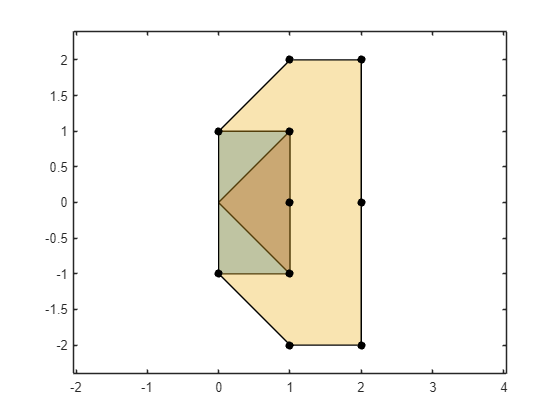

PA = polyshape(A);
PB = polyshape(B);
PM = polyshape(C);

fig = figure();
axe = axes(fig);
hold(axe,"on");
plot(PA);
plot(PB);
plot(PM);
f = @(p)scatter(p(1),p(2),'k',"filled");
cellfun(f,num2cell(M,2));
hold(axe,"off");
box(axe,"on");
axis(axe,"equal");